# Workflow - Create HDF5 file Format

**With this workflow, the user can create a project metaData variable that is further used to create specific sample meta data variables. At the end, HDF5 files are created automatically with a ranged mass spectra, a pos/epos file and a sample meta data variable **

## Create Meta Data File with the information for your project 

Open the meta data file template from the APT Toolbox

projectMeta = metaDataReadTextFile('experiment metadata list v1.txt');

open the MetaDataLEAP_03.mlapp and add the meta Workspace variable to the app.

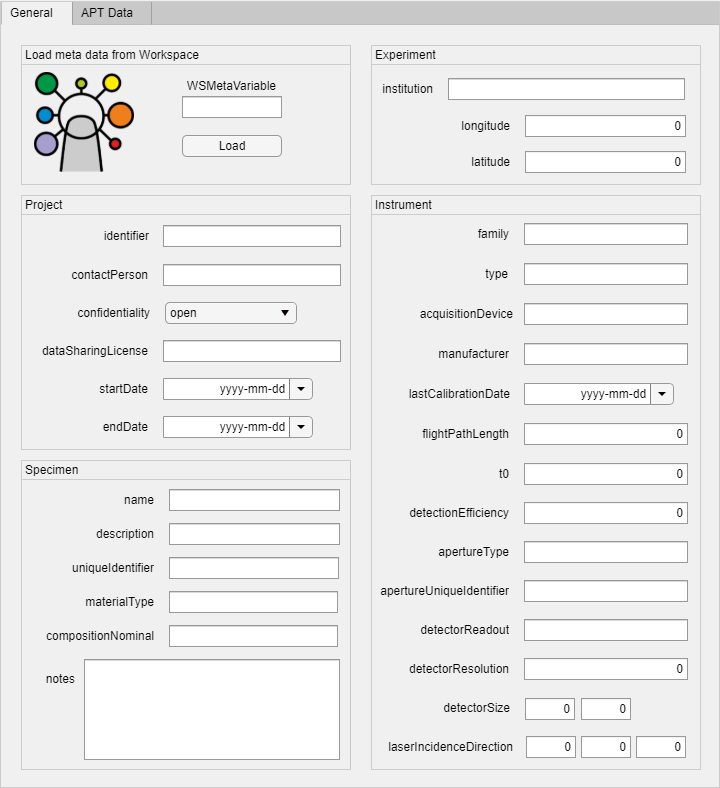

MetaDataLEAP_03

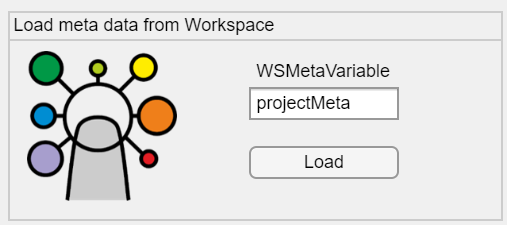

The user can now enter the specific attributes for your project, the institution and the instrument. If you also have specific APT Data Attributes that are the same for each measurement, the user can also add them.

Save everything as a projectMeta variable in the App under the tab APT Data to the workspace. 

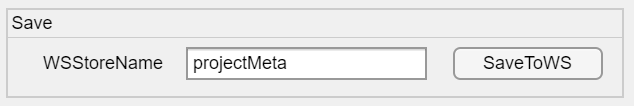

You can save the variable externaly in your project folder and reopen it for every new specimen. 

% save('projectMeta.mat', 'projectMeta');
% load('projectMeta.mat')

## Create Meta Data File for each sample

For each experiment with the LEAP you can extract experimental details and export it as an .csv file. After importing the table, measurement attributes are added to the meta Variable

fileName = 'Martina_Experiments.csv';
opts = detectImportOptions(fileName);
opts = setvartype(opts,{'PulseFraction___', 'LaserPolarization', 'LaserPulseEnergy_nJ_'}, 'double');
opts = setvartype(opts,{'Result', 'Operator', 'LocalElectrode'}, 'categorical');
disp([opts.VariableNames' opts.VariableTypes'])

    {'ExperimentID'        }    {'double'     }
    {'Specimen'            }    {'char'       }
    {'Project'             }    {'char'       }
    {'ProjectID'           }    {'double'     }
    {'Customer'            }    {'char'       }
    {'GoodHits'            }    {'double'     }
    {'Voltage_V_'          }    {'double'     }
    {'Temperature_K_'      }    {'double'     }
    {'RunTime_Hrs_'        }    {'double'     }
    {'Date'                }    {'datetime'   }
    {'Result'              }    {'categorical'}
    {'RunID'               }    {'char'       }
    {'Operator'            }    {'categorical'}
    {'LocalElectrode'      }    {'categorical'}
    {'GoodHits___'         }    {'double'     }
    {'PulseFraction___'    }    {'double'     }
    {'PulseFrequency_Hz_'  }    {'double'     }
    {'FlightPathLength_mm_'}    {'double'     }
    {'LaserPulseEnergy_nJ_'}    {'double'     }
    {'LaserPolarization'   }    {'double'     }
    {'Comments'            }    {'char' 

attrLEAP = readtable(fileName, opts);
clearvars opts
 

disp([opts.VariableNames' opts.VariableTypes']) should give the user this table. If the rows of your imported table have the wrong Variable Type. The user has to change the imported Variable types with setvartype.

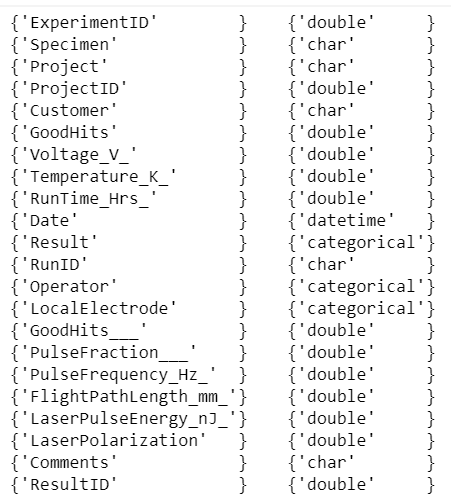

select the desired sample/measurement number

exNum = 4261; % add the unique LEAP experiment number
sampleMeta = metaDataReadLEAPAttributes(projectMeta, exNum, attrLEAP);
 

Open the MetaDataLEAP_03 and add the missing attributes of your measurement and save them as a workspace variable and in your project folder

% MetaDataLEAP_03
% save('sampleMeta.mat', 'sampleMeta');

## Create HDF5 file for each sample

You need a folder with your ranged Mass Spectra (Somewhere in the name has to be *mass*.fig), the pos/epos file and the meta data. Then you can run the script.

MassSpec figure is auatomatically loaded into matlab

fileListFig = dir('*mass*.fig'); 
file = fileListFig.name;
path = [fileListFig.folder, '\'];

Loading of ranges from figure

rangeFigureVisibility = 'invisible'; % or 'visible'
rngFig = openfig([path '/' file],rangeFigureVisibility);
spec = findobj( get(rngFig,'Children'), '-depth', 2, 'DisplayName', 'mass spectrum');
rangeTable = rangesExtractFromMassSpec(spec);
ionTable = ionsExtractFromMassSpec(spec);
close(rngFig);
clear file path rangeFigureVisibility;

Loading the epos/pos file

fileListFolder = dir('*.epos');
posIn = posToTable(fileListFolder.name);

Create the HDF5 file

hdf5FileCreateFromMetaDataList(fileName,metaData);
rangeTableAddToHDF5(fileName,rangeTable);
ionTableAddToHDF5(fileName,ionTable);
posTableAddToHDF5(fileName,posIn);

## Create HDF5 files automatically

The user needs for each measurement a folder that contains the ranged mass spectra, the pos/epos file and the Matlab metaData variable

topFolder = 'Z:\ProjectFolder';
fileList = dir([topFolder '/**/*.epos']);

for j = 1:length(fileList)
    
    folderName = fileList(j).folder;
    oldFolder = cd(folderName);
    % load Mass Spectra and extract rangeTable & ionTable
    fileListFig = dir('*mass*.fig'); 
    file = fileListFig.name;
    path = [fileListFig.folder, '\'];
    rangeFigureVisibility = 'invisible'; % or 'visible'
    rngFig = openfig([path file],rangeFigureVisibility);
    spec = findobj( get(rngFig,'Children'), '-depth', 2, 'DisplayName', 'mass spectrum');
    rangeTable = rangesExtractFromMassSpec(spec);
    ionTable = ionsExtractFromMassSpec(spec);
    close(rngFig);
    clear file path rangeFigureVisibility;
    % load pos/epos
    fileListFolder = dir('*.epos');
    posIn = posToTable(fileListFolder.name);
    % create name for HDF5 file
    sampleName = fileListFolder.name;
    sampleName(10:end) = [];
    fileName = [sampleName, '.h5'];
    
    metaDataName = dir('*meta*.mat');
    metaDataOri = load([metaDataName.folder '\' metaDataName.name]);
    metaData = struct2cell(metaDataOri);
    metaData = metaData{1,1};
    
    
    hdf5FileCreateFromMetaDataList(fileName,metaData);
    rangeTableAddToHDF5(fileName,rangeTable);
    ionTableAddToHDF5(fileName,ionTable);
    posTableAddToHDF5(fileName,posIn);
    clearvars -except topFolder fileList;

end

 